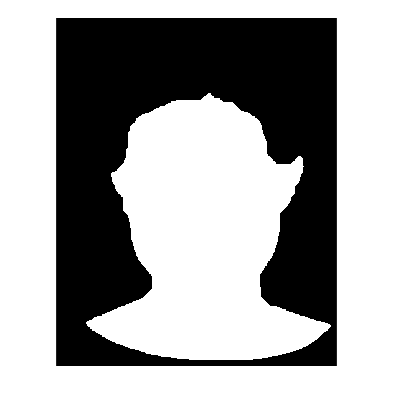

clear
% Read img file
img = imread("../db/DB0/db0_3.jpg");
img1 = double(img);

% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

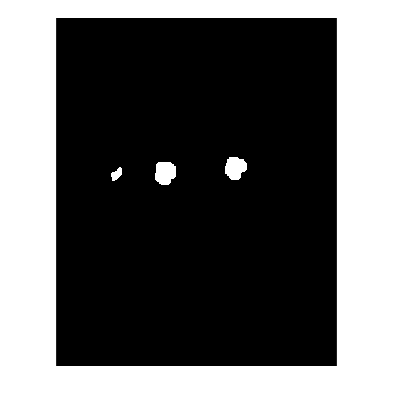


%Find eyes and a mouth
eyes = eyemap(img_gw);
% imshow(eyes)
eye_mask = eyemask(eyes) & face_mask;
imshow(eye_mask)

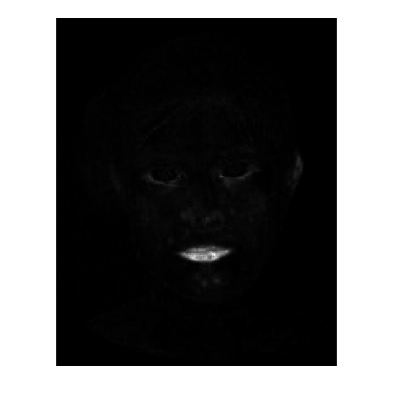


mouth = mouth_map(img_gw);
imshow(mouth)

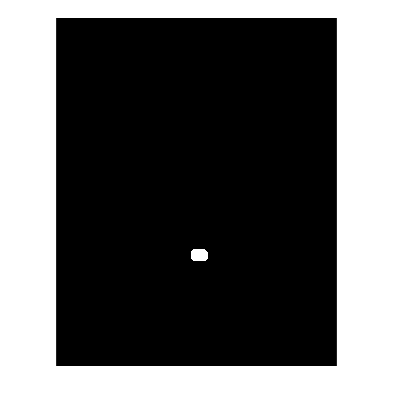

mouth_mask = mouthmask(mouth) & face_mask;

imshow(mouth_mask)

[x,y] = mouth_index(mouth_mask)

x = 230

y = 381


[indexX,indexY] = eye_index(eye_mask)

indexX =     97   176   288


indexY =    251   249   242


% Calculate the center of the mouth (you might need to adjust this based on your specific case)
mouth_center = [x, y]; % replace with actual coordinates

% Calculate the distance of each eye center from the mouth center
eye_centers = [indexX(:) + indexY(:)/2, eyes_bbox(:, 2) + eyes_bbox(:, 4)/2];
distances = sqrt(sum((eye_centers - mouth_center).^2, 2));

% Find the indices of the two eyes with the closest distance to the mouth
[~, sorted_indices] = sort(distances);
selected_eye_indices = sorted_indices(1:2);

% Extract the coordinates of the selected eyes
selected_eyes = eyes_bbox(selected_eye_indices, :);